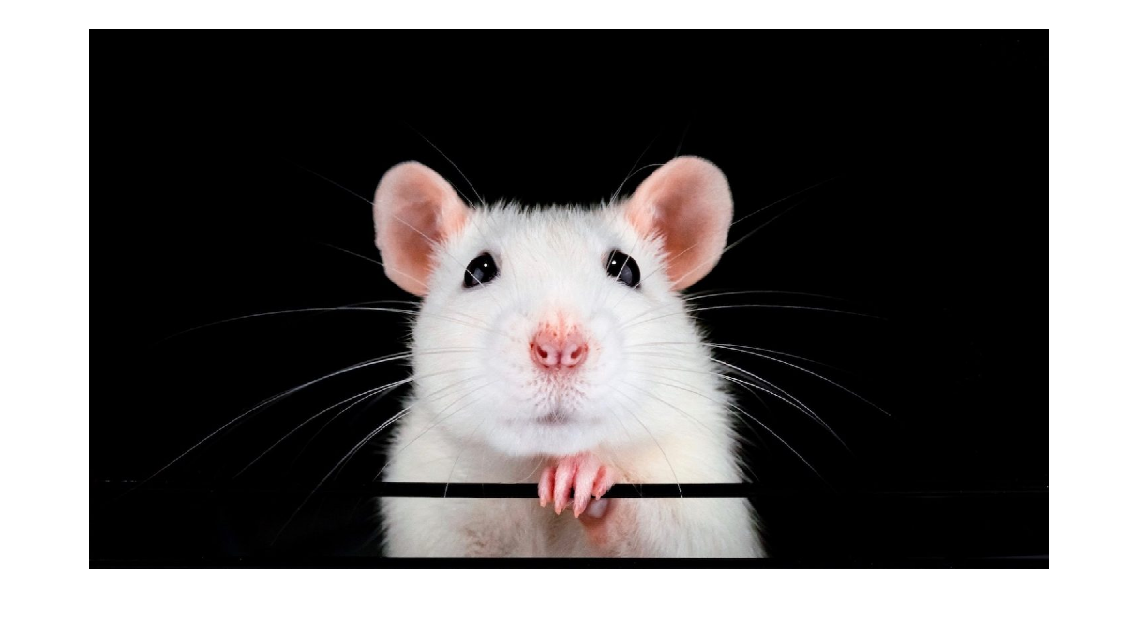

clc; clear; close all

img=imread('Test_rat_image2.jpg');
imshow(img)

I=rgb2gray(img);

%I_sobel=edge(I,'Sobel');
[I_test, threshold]=edge(I,'Canny');

Threshold

threshold

threshold =     0.0063    0.0156


I_edge=edge(I,'Canny',39* threshold);



Eye isolation

se90=strel('line',3,90);
se0=strel('line',3,0);
I_dilate=imdilate(I_edge,[se90 se0]);

I_fill=imfill(I_dilate,'holes');

I_erode=imerode(I_fill,[se90 se0]);
I_erode=imerode(I_erode,[se90 se0])

I_erode = 810×1440 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

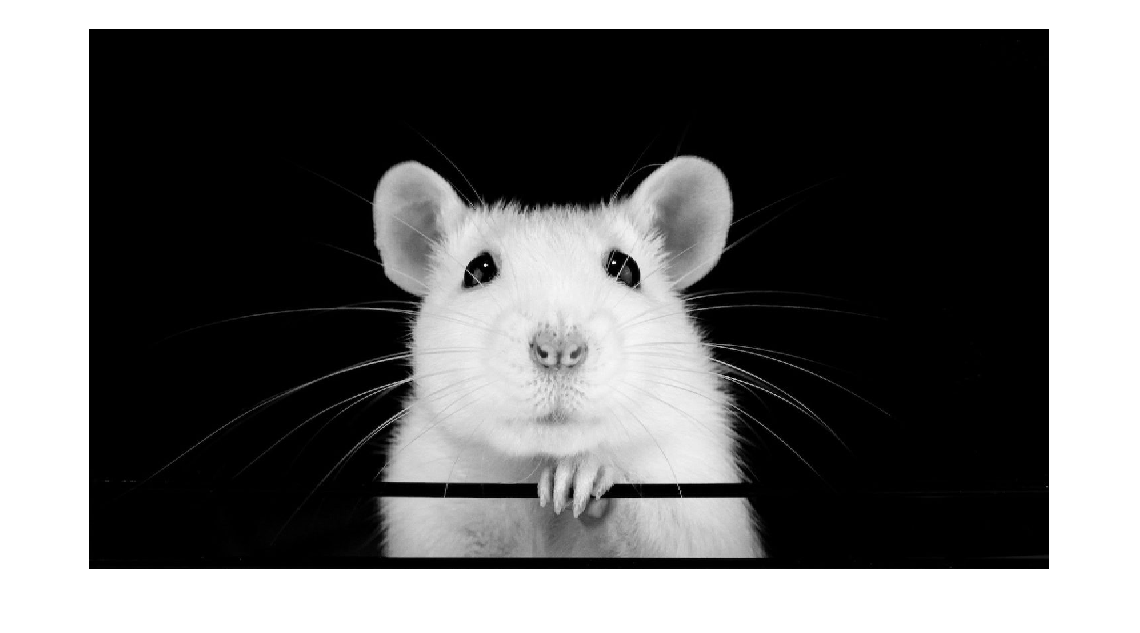

I_clear=imclearborder(I_erode);

imshow(I)

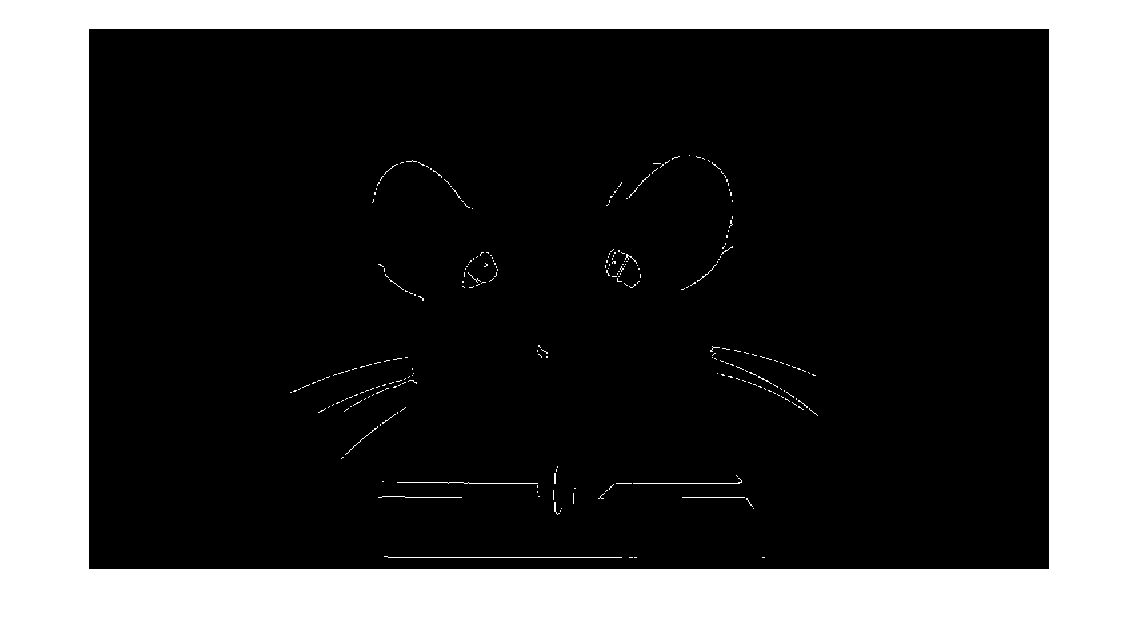

imshow(I_edge)

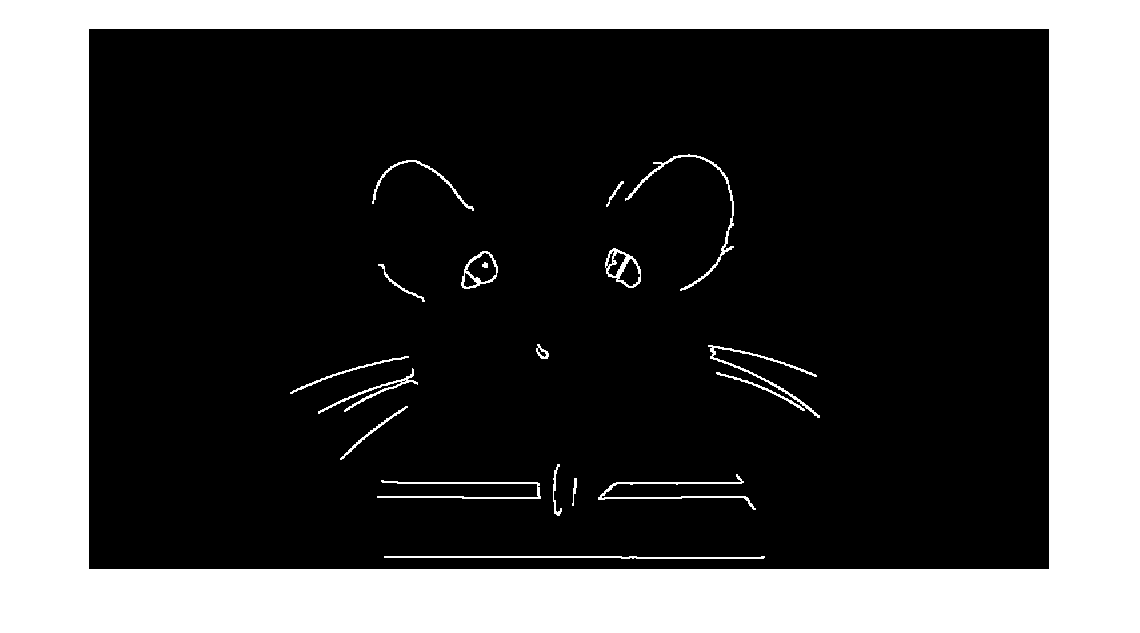


imshow(I_dilate)

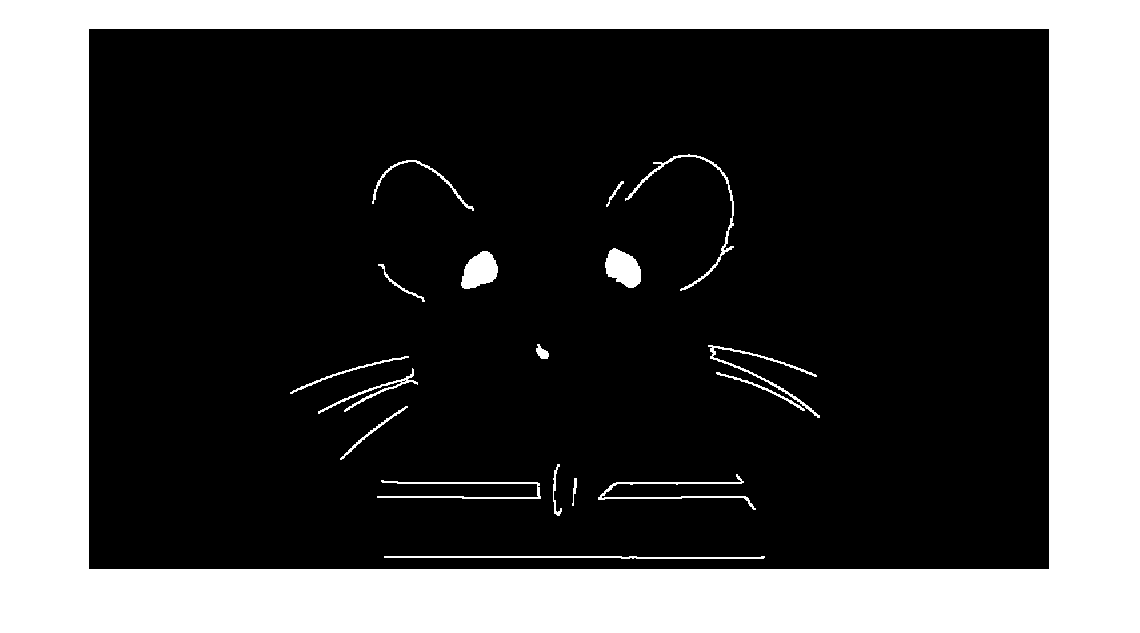

imshow(I_fill)

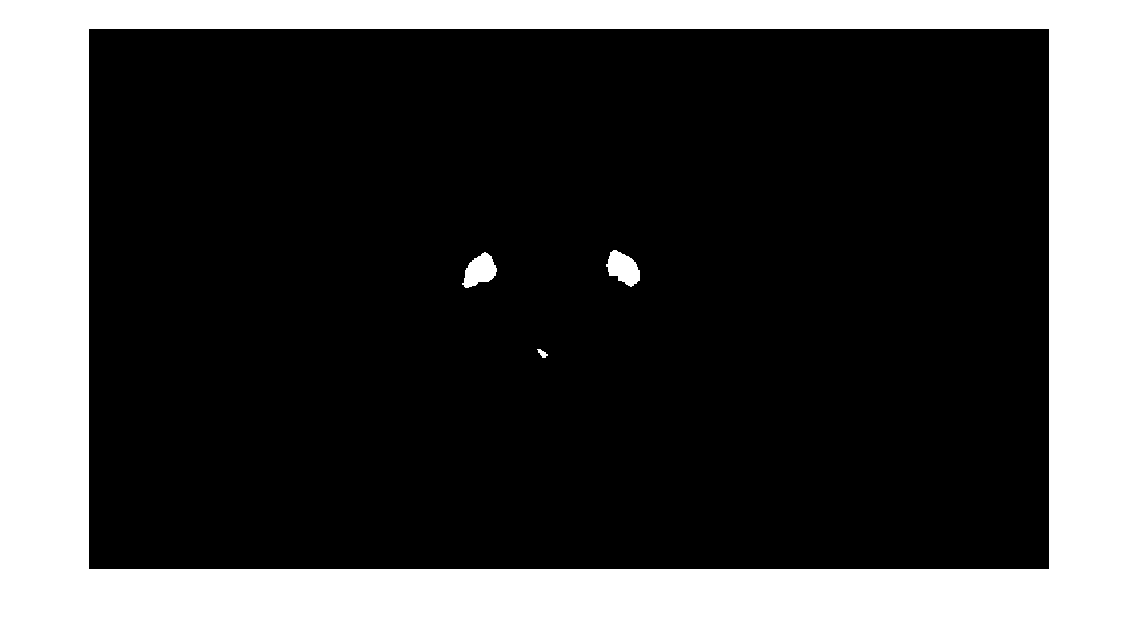

imshow(I_erode)

imshow(I_clear)

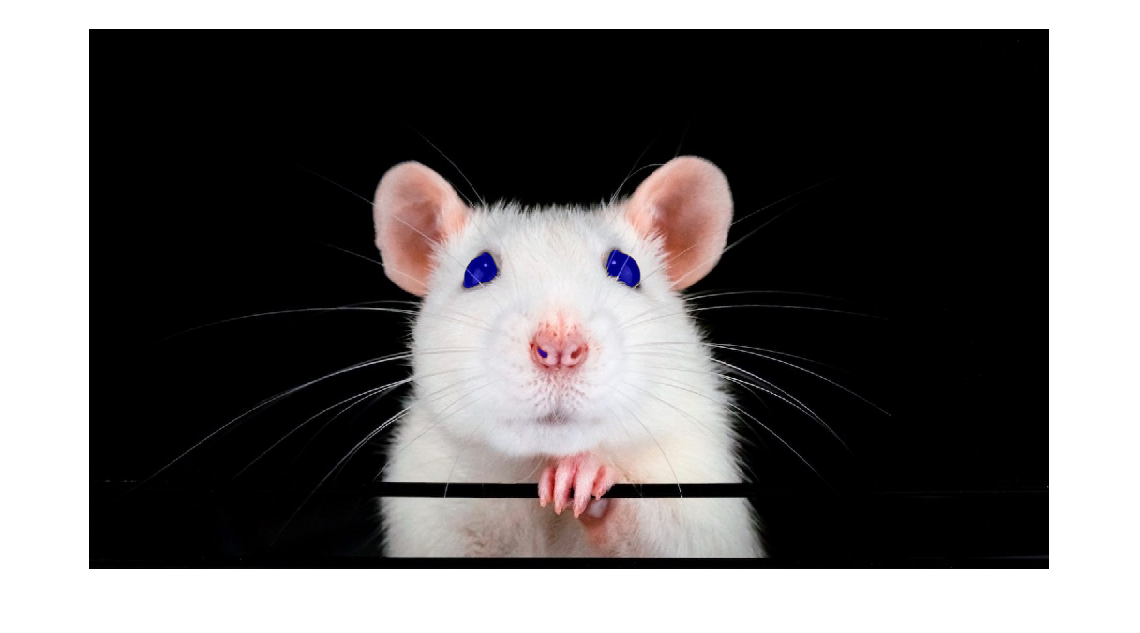


imshow(labeloverlay(img,I_clear))